clear all
close all
clc

rng(1);

load('Benchmark_EEG_small')


Preprocessing Data

partici = 3    %Choose participant

partici = 3

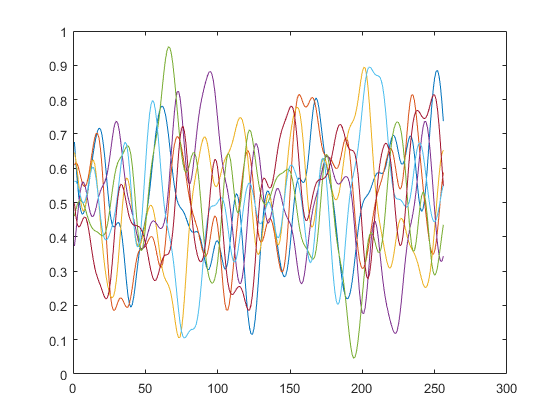


input = squeeze(data.u(partici,:,:))' /6+0.5 ;
output = squeeze(data.y(partici,:,:))'/8+0.5 ;

plot(input)

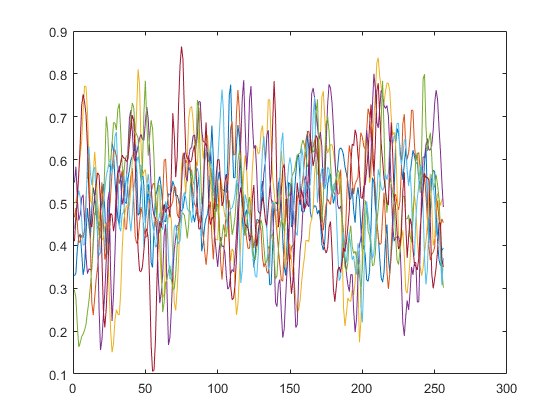

plot(output)


% histogram(input);
% histogram(output);


Choose lags

%angle
inlags=[10 9 8 6 5 4];
for l = 1:length(inlags)
u(:,l) = (reshape(input(end-inlags(l)-241:end-inlags(l)-1,:), [],1));
end

%angular velocity
vlags=[4 5 6];
for l = 1:length(vlags)
v(:,l) = (reshape(input(end-vlags(l)-241:end-vlags(l)-1,:), [],1) - reshape(input(end-vlags(l)-240:end-vlags(l),:), [],1))/0.2+0.5;
end

%output
outlags=[0 1 2 3 4 5];
for l = 1:length(outlags)
y(:,l) = reshape(output(end-outlags(l)-240:end-outlags(l),:), [],1);
end


Split test and training set

for period = 1:7;
testind = (241*(period-1)+1):241*period;

trainind = setdiff([1:size(u,1)],testind);

featurez = [y(trainind,2:end)  v(trainind,:) u(trainind,:)];
zeta = y(trainind,1);

tfeaturez = [y(testind,2:end)  v(testind,:) u(testind,:)];
yt = y(testind,1);



% histogram(featurez(:,1),100)
% 
% inters = 0:0.005:0.995;
% for s = 1:200
% groupz{s} = (featurez(:,1)>= inters(s) & featurez(:,1)< inters(s)+0.005);
% end
% 
% sampled = [];
% sampledzeta= [];
% for s = 1:200
%     if ~isempty(featurez(groupz{s},:))      
% [sam,idx] = datasample(featurez(groupz{s},:),40,1);
% sampled = [sampled ; sam];
% zet = zeta(groupz{s});
% sampledzeta =  [sampledzeta ; zet(idx')];
%     end
% end
% 
% 
% histogram(sampled(:,1),200);
% histogram(sampledzeta(:,1),200);

% 
% featurez = sampled;
% zeta = sampledzeta;


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                 %degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines

un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 10;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 1.6212e-05


Compression: 1.6212e-05


Compression: 1.6212e-05


Compression: 1.6212e-05


Compression: 1.6212e-05


Compression: 1.6212e-05


Compression: 1.6212e-05


Optimize TT cores

lambda=1*10^-3 ;
gamma=0 ;
% gamma=;

difforder=2;
MAXITR = 2*d;
MAXRANK = 10;
epsilon = 10^-3;
rez = [];
% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

% [TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);
[TN,Vm,Vp,res1,res2,saveR] = optimTTsals(TN,Vm,Vp,un,zeta,MAXITR,MAXRANK,nselect,lambda,epsilon,difforder);

    "iteration:"    "1"    "0.48594"

    "iteration:"    "2"    "0.99449"

    "iteration:"    "3"    "1.0666"

    "iteration:"    "4"    "1.0996"

    "iteration:"    "5"    "1.1255"

    "iteration:"    "6"    "1.1483"

    "iteration:"    "7"    "1.1823"

    "iteration:"    "8"    "1.2278"

    "iteration:"    "9"    "1.2745"

    "iteration:"    "10"    "1.3163"

    "iteration:"    "11"    "1.3713"

    "iteration:"    "12"    "1.4075"

    "iteration:"    "13"    "1.437"

    "iteration:"    "14"    "1.4648"

    "iteration:"    "15"    "1.4928"

    "iteration:"    "16"    "1.5153"

    "iteration:"    "17"    "1.5396"

    "iteration:"    "18"    "1.5527"

    "iteration:"    "19"    "1.5762"

    "iteration:"    "20"    "1.6017"

    "iteration:"    "21"    "1.6233"

    "iteration:"    "22"    "1.6438"

    "iteration:"    "23"    "1.6641"

    "iteration:"    "24"    "1.6854"

    "iteration:"    "25"    "1.7077"

    "iteration:"    "26"    "1.7331"

    "iteration:"    

    "iteration:"    "1"    "0.41089"

    "iteration:"    "2"    "0.81769"

    "iteration:"    "3"    "0.91849"

    "iteration:"    "4"    "0.94765"

    "iteration:"    "5"    "0.96976"

    "iteration:"    "6"    "0.98374"

    "iteration:"    "7"    "1.01"

    "iteration:"    "8"    "1.0588"

    "iteration:"    "9"    "1.0907"

    "iteration:"    "10"    "1.1258"

    "iteration:"    "11"    "1.1583"

    "iteration:"    "12"    "1.1855"

    "iteration:"    "13"    "1.2104"

    "iteration:"    "14"    "1.2363"

    "iteration:"    "15"    "1.2676"

    "iteration:"    "16"    "1.2976"

    "iteration:"    "17"    "1.3262"

    "iteration:"    "18"    "1.3554"

    "iteration:"    "19"    "1.3862"

    "iteration:"    "20"    "1.4065"

    "iteration:"    "21"    "1.4285"

    "iteration:"    "22"    "1.4454"

    "iteration:"    "23"    "1.4649"

    "iteration:"    "24"    "1.4865"

    "iteration:"    "25"    "1.5054"

    "iteration:"    "26"    "1.5344"

    "iteration:" 

    "iteration:"    "1"    "0.41571"

    "iteration:"    "2"    "0.89463"

    "iteration:"    "3"    "0.98437"

    "iteration:"    "4"    "1.0062"

    "iteration:"    "5"    "1.0339"

    "iteration:"    "6"    "1.0546"

    "iteration:"    "7"    "1.0764"

    "iteration:"    "8"    "1.098"

    "iteration:"    "9"    "1.1217"

    "iteration:"    "10"    "1.1472"

    "iteration:"    "11"    "1.1693"

    "iteration:"    "12"    "1.191"

    "iteration:"    "13"    "1.2127"

    "iteration:"    "14"    "1.2312"

    "iteration:"    "15"    "1.2472"

    "iteration:"    "16"    "1.2644"

    "iteration:"    "17"    "1.2799"

    "iteration:"    "18"    "1.3004"

    "iteration:"    "19"    "1.3222"

    "iteration:"    "20"    "1.3434"

    "iteration:"    "21"    "1.3678"

    "iteration:"    "22"    "1.4062"

    "iteration:"    "23"    "1.4578"

    "iteration:"    "24"    "1.4999"

    "iteration:"    "25"    "1.5458"

    "iteration:"    "26"    "1.5874"

    "iteration:"    

    "iteration:"    "1"    "0.40552"

    "iteration:"    "2"    "0.80688"

    "iteration:"    "3"    "0.86928"

    "iteration:"    "4"    "0.88963"

    "iteration:"    "5"    "0.91135"

    "iteration:"    "6"    "0.93627"

    "iteration:"    "7"    "0.9555"

    "iteration:"    "8"    "0.9846"

    "iteration:"    "9"    "1.0132"

    "iteration:"    "10"    "1.0364"

    "iteration:"    "11"    "1.0602"

    "iteration:"    "12"    "1.0732"

    "iteration:"    "13"    "1.0921"

    "iteration:"    "14"    "1.1122"

    "iteration:"    "15"    "1.133"

    "iteration:"    "16"    "1.1586"

    "iteration:"    "17"    "1.1802"

    "iteration:"    "18"    "1.1951"

    "iteration:"    "19"    "1.2095"

    "iteration:"    "20"    "1.2296"

    "iteration:"    "21"    "1.2546"

    "iteration:"    "22"    "1.3027"

    "iteration:"    "23"    "1.3248"

    "iteration:"    "24"    "1.3386"

    "iteration:"    "25"    "1.3597"

    "iteration:"    "26"    "1.3798"

    "iteration:"

    "iteration:"    "1"    "0.41821"

    "iteration:"    "2"    "0.87697"

    "iteration:"    "3"    "0.93902"

    "iteration:"    "4"    "0.95883"

    "iteration:"    "5"    "0.97904"

    "iteration:"    "6"    "1.0004"

    "iteration:"    "7"    "1.0636"

    "iteration:"    "8"    "1.0993"

    "iteration:"    "9"    "1.1421"

    "iteration:"    "10"    "1.1673"

    "iteration:"    "11"    "1.1965"

    "iteration:"    "12"    "1.2206"

    "iteration:"    "13"    "1.2425"

    "iteration:"    "14"    "1.2628"

    "iteration:"    "15"    "1.2867"

    "iteration:"    "16"    "1.3098"

    "iteration:"    "17"    "1.343"

    "iteration:"    "18"    "1.3621"

    "iteration:"    "19"    "1.3822"

    "iteration:"    "20"    "1.4036"

    "iteration:"    "21"    "1.4248"

    "iteration:"    "22"    "1.4469"

    "iteration:"    "23"    "1.4664"

    "iteration:"    "24"    "1.4833"

    "iteration:"    "25"    "1.5031"

    "iteration:"    "26"    "1.5245"

    "iteration:" 

    "iteration:"    "1"    "0.5049"

    "iteration:"    "2"    "0.97223"

    "iteration:"    "3"    "1.0338"

    "iteration:"    "4"    "1.0616"

    "iteration:"    "5"    "1.0828"

    "iteration:"    "6"    "1.1044"

    "iteration:"    "7"    "1.1261"

    "iteration:"    "8"    "1.1386"

    "iteration:"    "9"    "1.1595"

    "iteration:"    "10"    "1.1783"

    "iteration:"    "11"    "1.1976"

    "iteration:"    "12"    "1.2196"

    "iteration:"    "13"    "1.239"

    "iteration:"    "14"    "1.2594"

    "iteration:"    "15"    "1.273"

    "iteration:"    "16"    "1.292"

    "iteration:"    "17"    "1.3111"

    "iteration:"    "18"    "1.3335"

    "iteration:"    "19"    "1.3535"

    "iteration:"    "20"    "1.3758"

    "iteration:"    "21"    "1.3906"

    "iteration:"    "22"    "1.405"

    "iteration:"    "23"    "1.4236"

    "iteration:"    "24"    "1.4446"

    "iteration:"    "25"    "1.4646"

    "iteration:"    "26"    "1.5062"

    "iteration:"    "27"

    "iteration:"    "1"    "0.44541"

    "iteration:"    "2"    "0.86918"

    "iteration:"    "3"    "0.92721"

    "iteration:"    "4"    "0.95167"

    "iteration:"    "5"    "0.97207"

    "iteration:"    "6"    "0.99088"

    "iteration:"    "7"    "1.0079"

    "iteration:"    "8"    "1.0279"

    "iteration:"    "9"    "1.0527"

    "iteration:"    "10"    "1.0713"

    "iteration:"    "11"    "1.0939"

    "iteration:"    "12"    "1.1327"

    "iteration:"    "13"    "1.1713"

    "iteration:"    "14"    "1.2199"

    "iteration:"    "15"    "1.252"

    "iteration:"    "16"    "1.2753"

    "iteration:"    "17"    "1.2935"

    "iteration:"    "18"    "1.3115"

    "iteration:"    "19"    "1.3291"

    "iteration:"    "20"    "1.3481"

    "iteration:"    "21"    "1.3686"

    "iteration:"    "22"    "1.3855"

    "iteration:"    "23"    "1.4014"

    "iteration:"    "24"    "1.4252"

    "iteration:"    "25"    "1.4433"

    "iteration:"    "26"    "1.4614"

    "iteration:"


table(saveR)

ans = 28×1 table
        saveR    
    _____________

    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]


ans = 28×1 table
        saveR    
    _____________

    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]


ans = 28×1 table
        saveR    
    _____________

    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]


ans = 28×1 table
        saveR    
    _____________

    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]


ans = 28×1 table
        saveR    
    _____________

    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]


ans = 28×1 table
        saveR    
    _____________

    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]


ans = 28×1 table
        saveR    
    _____________

    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]
    [1×15 double]


% 
% plot(res1)
% plot(res2)
% 
% trainerror = res1(end)
% 
% plot(rez)

Evaluate Test data


% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% plot(zeta)
% plot(yhattrain)
% hold off
% axis([0 256 -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)


yhat = evalspline(TN,tfeaturez,n,m);


erboi = (yhat-yt);
% histogram((erboi)');
VAF1(period) = 1-var(erboi)/var(yt);
% MSE = immse(yhat,yt)
% 
% figure
% hold on
% plot(yt)
% plot(yhat)
% hold off
% axis([0 256 -inf inf])
% 
% %  Visualize errors
% [sortout,Iss]=sort(yhat);
% figure
% hold on
% plot(yt(Iss))
% plot(sortout,'Linewidth',3)
% hold off
% 
% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off

simfeaturez = tfeaturez;

for j = 1:3
y_k = evalspline(TN,simfeaturez,n,m);

for k = 5:-1:2
simfeaturez(k:end,k) = simfeaturez((k-1):end-1,(k-1));
end
simfeaturez(2:end,1) = y_k(1:end-1);

end

ysim = simfeaturez(4:end,1);

% figure
% hold on
% plot(yt(2:end-2),'linewidth',2)
% plot(ysim,'linewidth',2)
% hold off
% axis([0 256 -inf inf])

VAF(period) = 1-var(yt(2:end-2)-ysim)/var(yt);

end

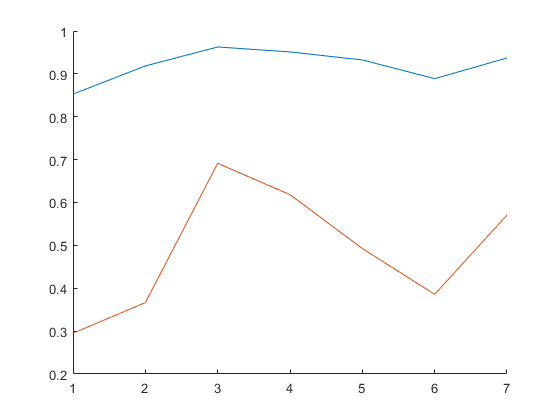

figure 
hold on
plot(VAF1)
plot(VAF)
hold off

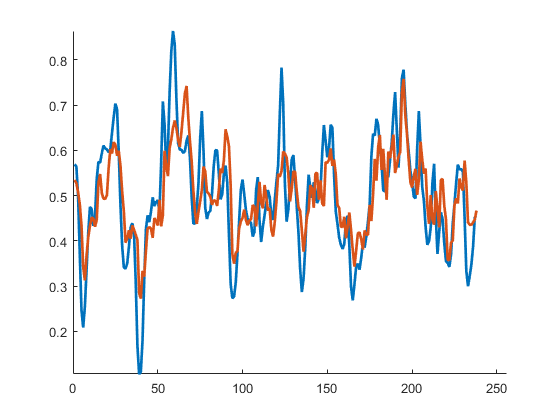


figure
hold on
plot(yt(2:end-2),'linewidth',2)
plot(ysim,'linewidth',2)
hold off
axis([0 256 -inf inf])


meanOSA = mean(VAF1)

meanOSA = 0.9206

meanMSA = mean(VAF)

meanMSA = 0.4887

% 
% 
% FY = mag2db(abs(fft(simfeaturez(3:end,1))));
% FZ = mag2db(abs(fft(yt)));
% 
% % heatmap(simfeaturez)
% % imagesc(simfeaturez)
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off